# X-Ray Classification of COVID-19 using Deeplearning

Creates a simple CNN for image classification.

by Joshua Rothe, heavily adapted from [https://www.mathworks.com/help/deeplearning/gs/create-simple-deep-learning-classification-network.html](https://www.mathworks.com/help/deeplearning/gs/create-simple-deep-learning-classification-network.html) 

% Load data and lable data based on folder name
xrayDatasetPath = char('./data/');
% imageDatastore only loads images as theyre used, improving performance
imds = imageDatastore(xrayDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% Split data into training and validation sets
numTrainFiles = 1000;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

% Define network architecture - 3 classes, images are 299x299
inputSize = [299 299 1];
numClasses = 3;
layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

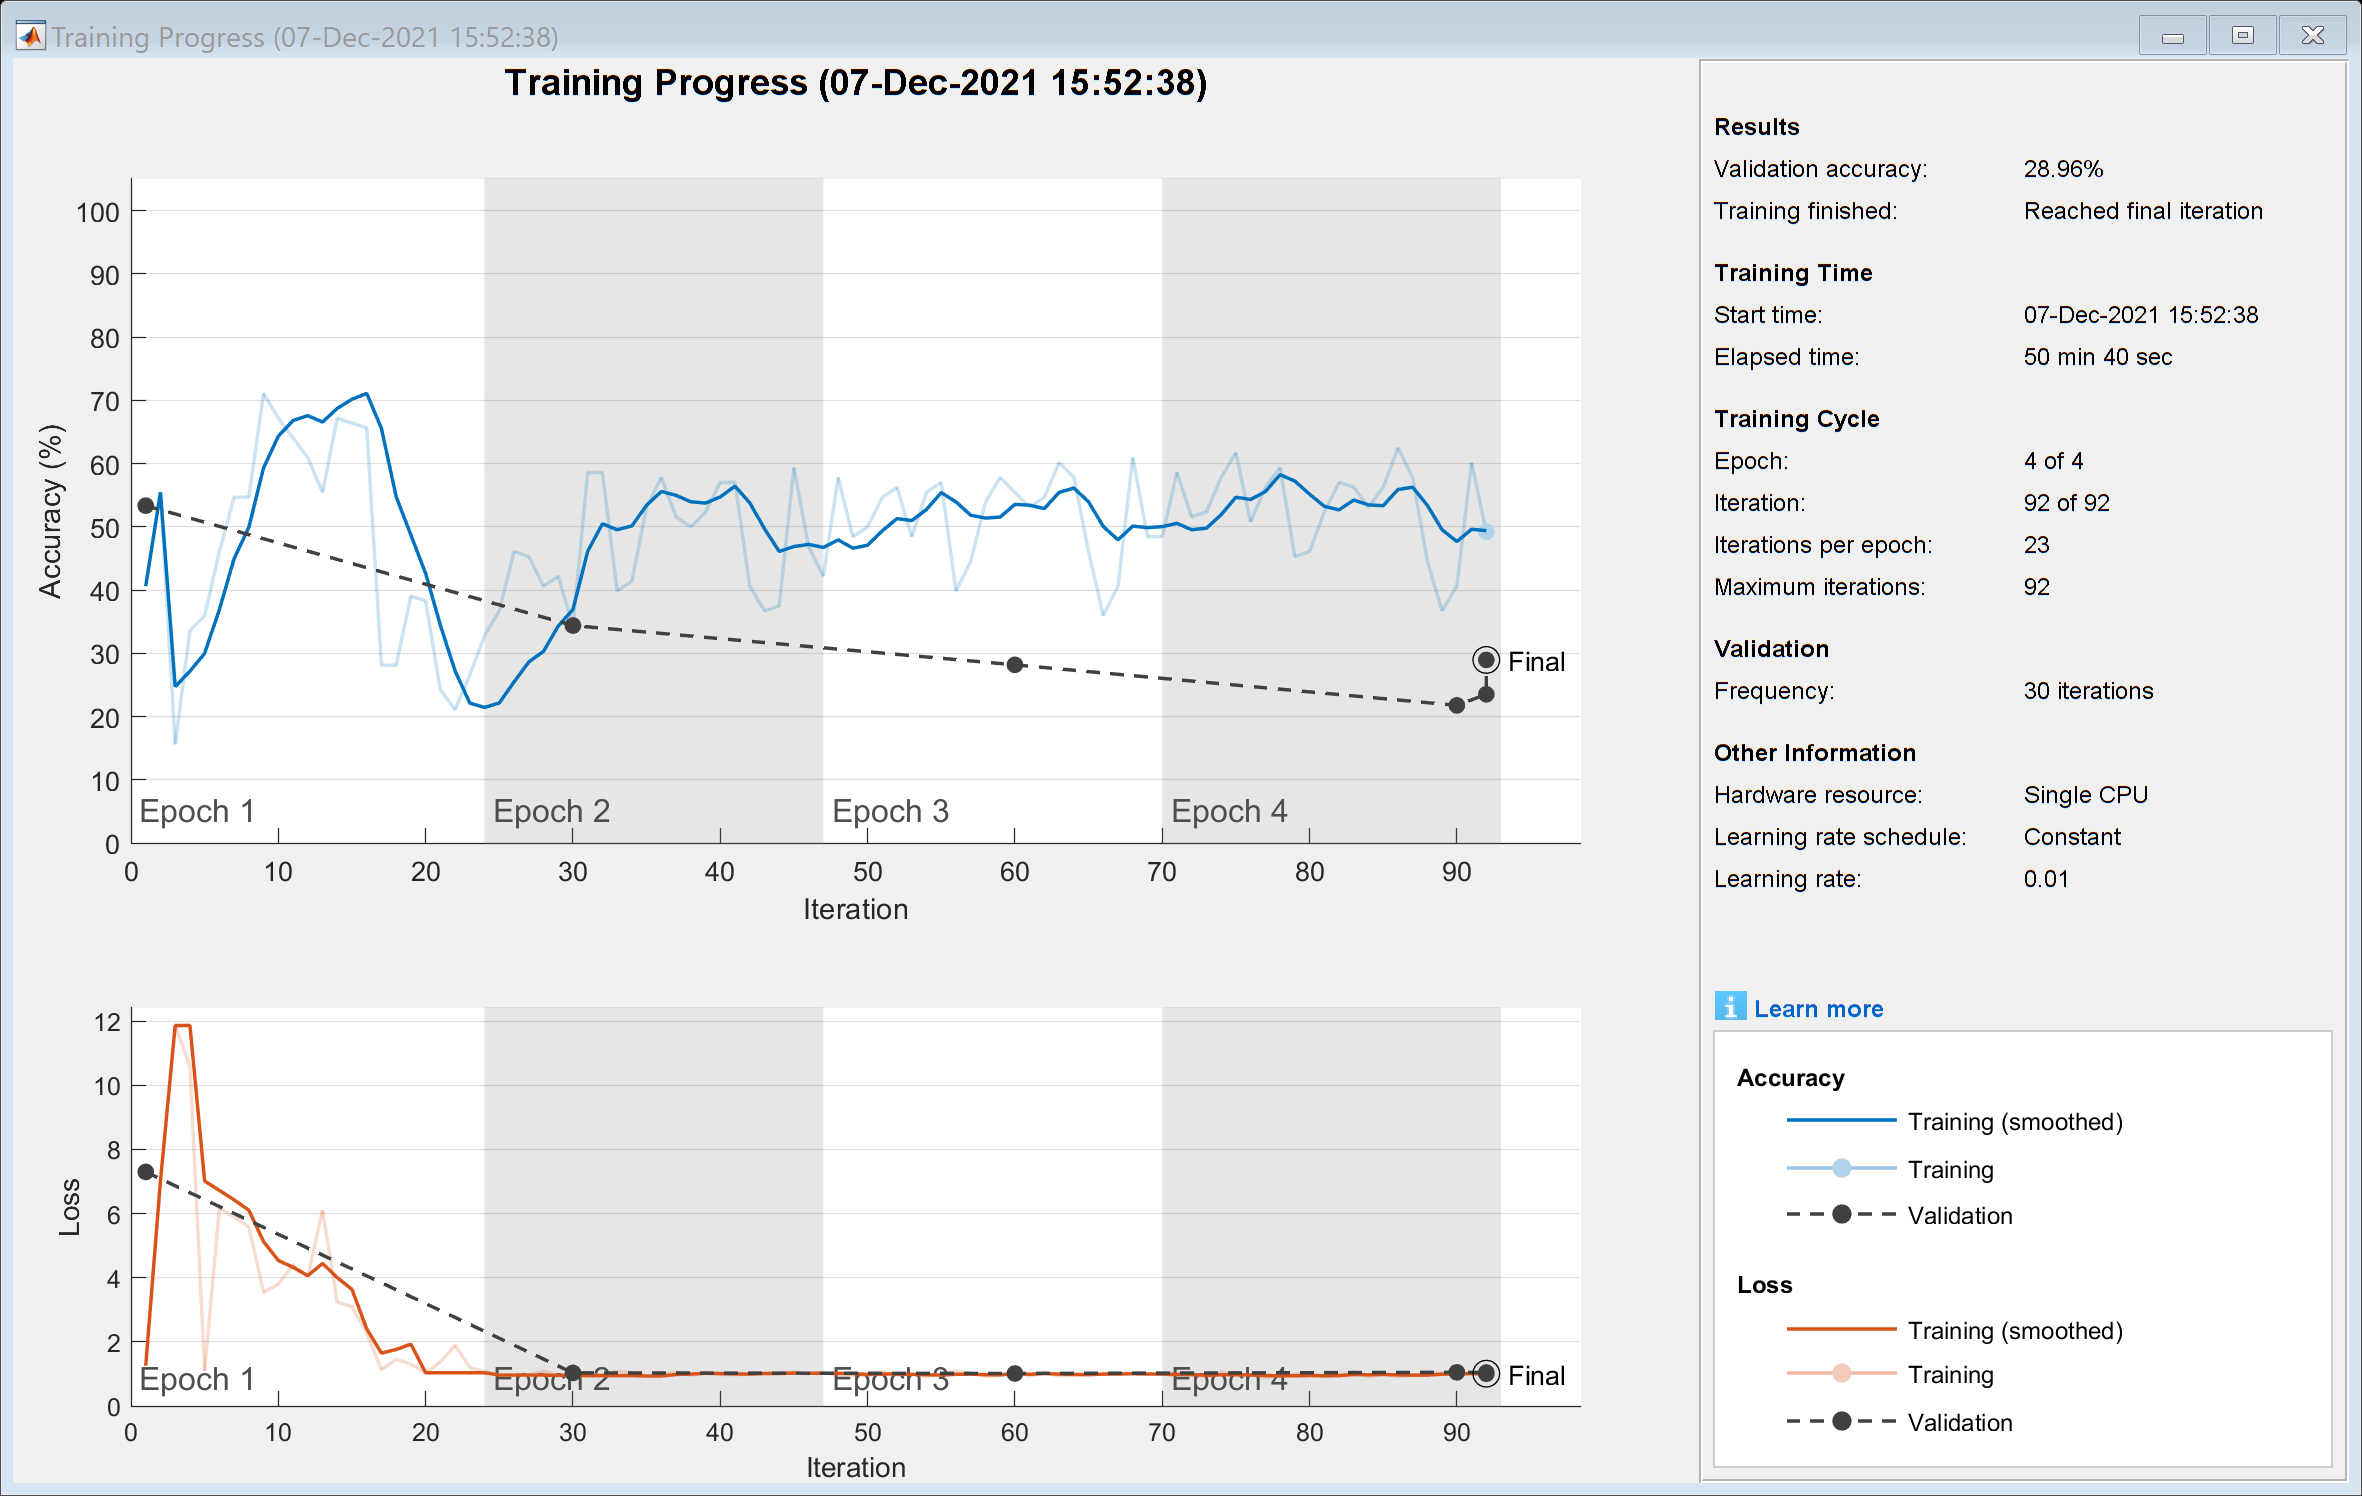

% Specify options and train network
options = trainingOptions('sgdm', ...
    'MaxEpochs',4, ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(imdsTrain,layers,options);

% Classify the validation data, check accuracy
YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.2896